% Folder path (change to your "baseline" folder path)
folderPath = "C:\Users\thamilezai\Downloads\JHU\Pre Work\My Work\baseline";
isfolder(folderPath)

ans = logical
   1



% Get a list of all files in the folder (.bin files)
fileList = dir(fullfile(folderPath, '*.bin'))

fileList = 5×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


Processing file 1 of 5: 2025.08.01.16.12.18_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


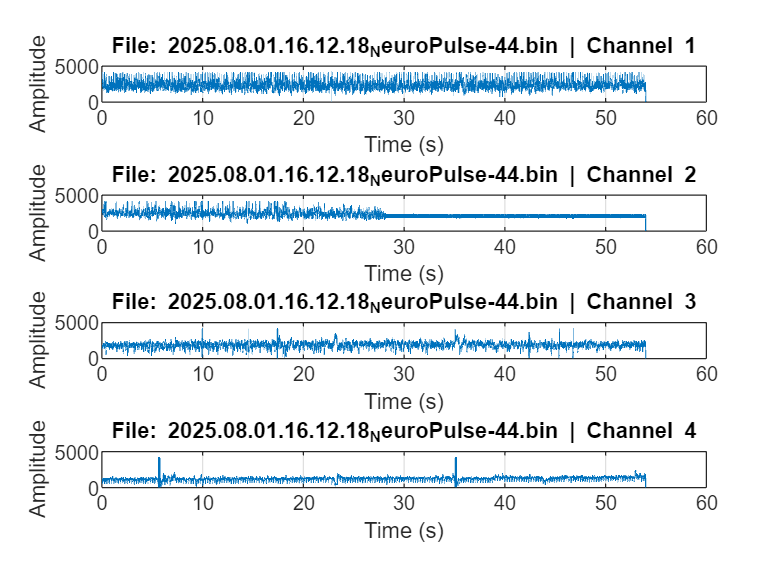

Processing file 2 of 5: 2025.08.01.16.43.55_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Progress: 100%
Unpacking Completed! 


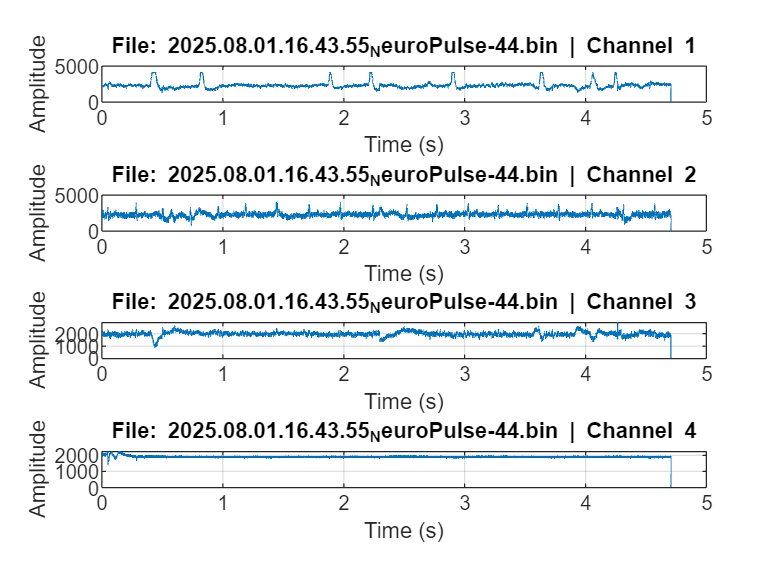

Processing file 3 of 5: 2025.08.01.16.45.11_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Progress: 100%
Unpacking Completed! 


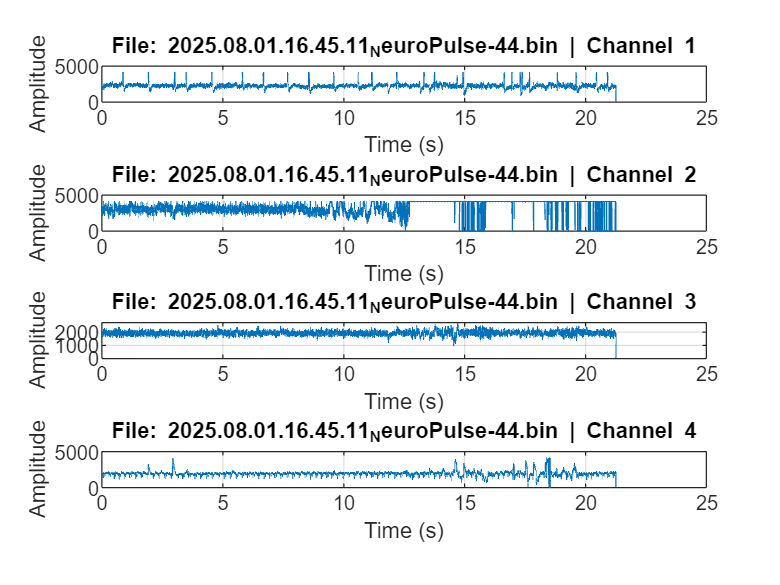

Processing file 4 of 5: 2025.08.01.16.51.07_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


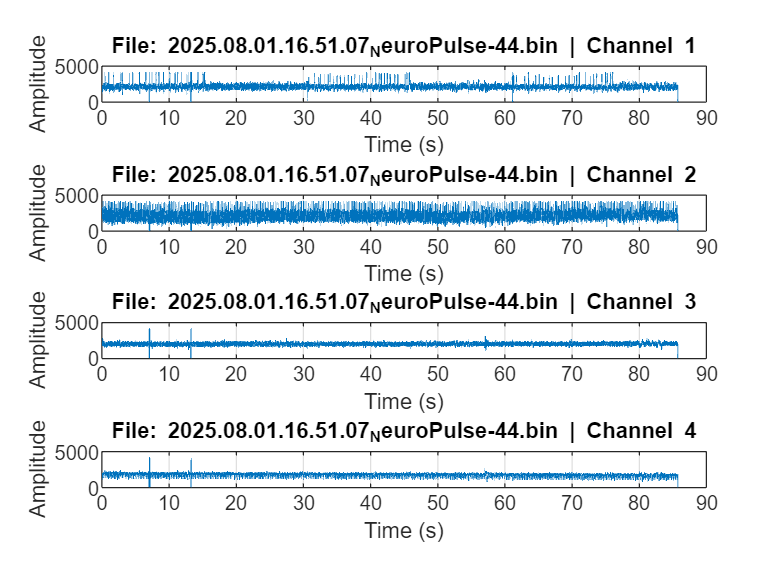

Processing file 5 of 5: 2025.08.01.16.59.13_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


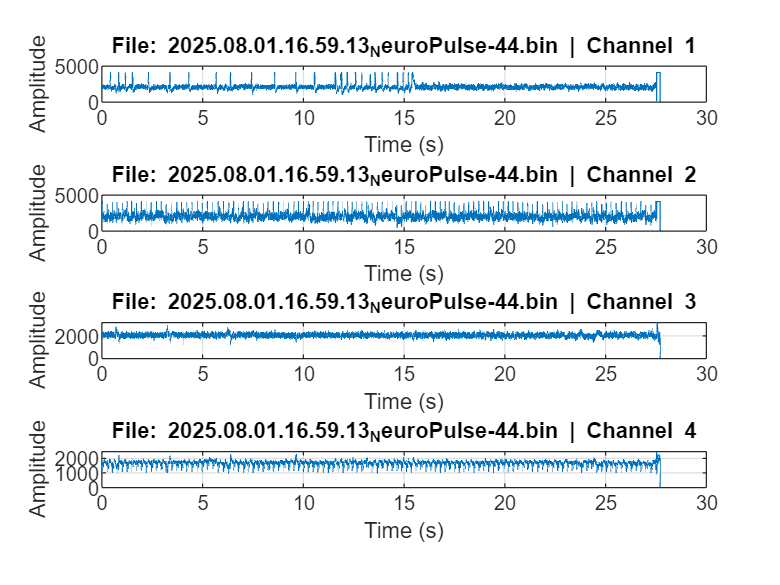

stdVals = zeros(5,4);
kurtVals = zeros(5,4);
skewVals = zeros(5,4);
names = zeros(5,4);

% Loop over each file
for i = 1:length(fileList)
    % Full file path
    filePath = fullfile(folderPath, fileList(i).name);
    
    % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
    
    % Call your unpack function
    unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    data = unpackedFile.channelsData;
    t    = unpackedFile.time;
    stdVals(i,1)  = std(data(1,:));
    stdVals(i,2)  = std(data(2,:));
    stdVals(i,3)  = std(data(3,:));
    stdVals(i,4)  = std(data(4,:));

     kurtVals(i,1)  = kurtosis(data(1,:));
     kurtVals(i,2)  = kurtosis(data(2,:));
     kurtVals(i,3)  = kurtosis(data(3,:));
     kurtVals(i,4)  = kurtosis(data(4,:));

     skewVals(i,1)  = skewness(data(1,:));
     skewVals(i,2)  = skewness(data(2,:));
     skewVals(i,3)  = skewness(data(3,:));
     skewVals(i,4)  = skewness(data(4,:));

    

    %Plot all channels
    figure;
    for ch = 1:unpackedFile.numChannels
        subplot(unpackedFile.numChannels,1,ch);
        plot(t, data(ch,:));
        xlabel('Time (s)');
        ylabel('Amplitude');
        title(['File: ', fileList(i).name, ' | Channel ', num2str(ch)]);
        grid on;
    end
end

stdTable   = table(names, stdVals,   'VariableNames', {'File','StdDev'});
kurtTable  = table(names, kurtVals,  'VariableNames', {'File','Kurtosis'});
skewTable  = table(names, skewVals,  'VariableNames', {'File','Skewness'});


stdTable = array2table(stdVals, ...
    'VariableNames', {'Channel1','Channel2','Channel3','Channel4'});
kurtTable = array2table(kurtVals, ...
    'VariableNames', {'Channel1','Channel2','Channel3','Channel4'});
skewTable = array2table(skewVals, ...
    'VariableNames', {'Channel1','Channel2','Channel3','Channel4'});

% Display results
disp('Standard Deviation Table:');

Standard Deviation Table:


disp(stdTable);

    Channel1    Channel2    Channel3    Channel4
    ________    ________    ________    ________

     454.04      376.63      354.51      241.82 
     422.68      315.35      174.95      55.684 
     377.84      647.02      127.28      330.77 
     305.63      406.46      120.65      161.73 
     383.34      443.06      130.96      146.32 




disp('Kurtosis Table:');

Kurtosis Table:


disp(kurtTable);

    Channel1    Channel2    Channel3    Channel4
    ________    ________    ________    ________

     4.4539      8.8439      5.9194      22.776 
     11.034      6.9712      9.2111      197.79 
     13.602      2.5745      6.9643      13.907 
     15.975       5.937      9.9301      6.2374 
     17.277       8.025      8.0453      5.5718 




disp('Skewness Table:');

Skewness Table:


disp(skewTable);

    Channel1    Channel2    Channel3    Channel4
    ________    ________    ________    ________

    0.82064      1.9064     -0.19365     0.63622
     2.4071      0.8097     -0.92636     -4.4996
     2.3044     -0.5746     -0.11463      1.2309
     2.2678      1.0207     0.073259    -0.95857
     3.2317       1.609      0.18905    -0.91582



Processing file 1 of 5: 2025.08.01.16.12.18_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


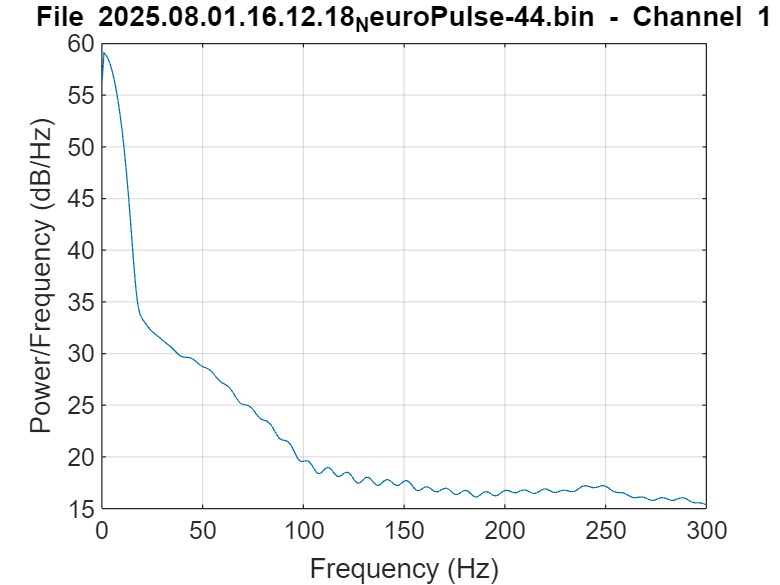

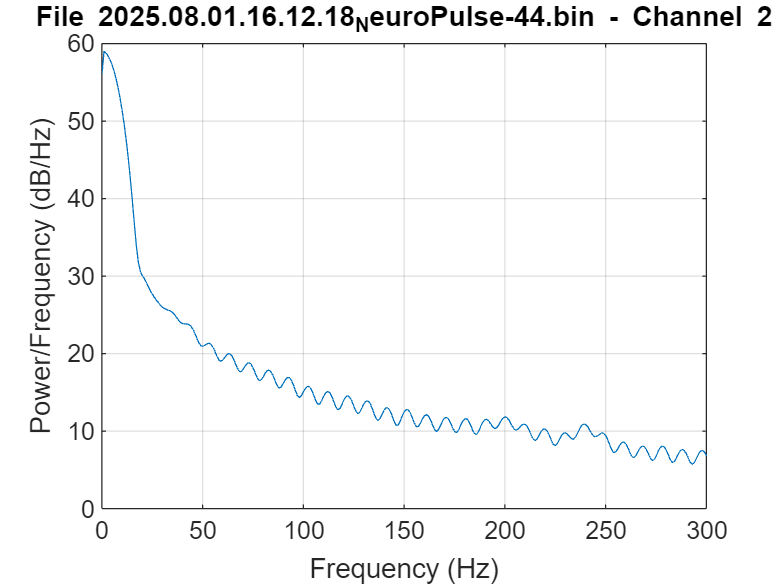

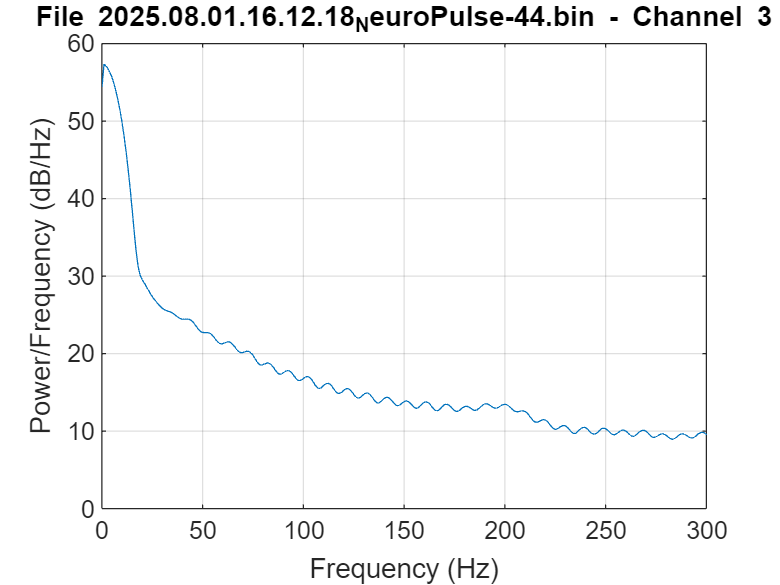

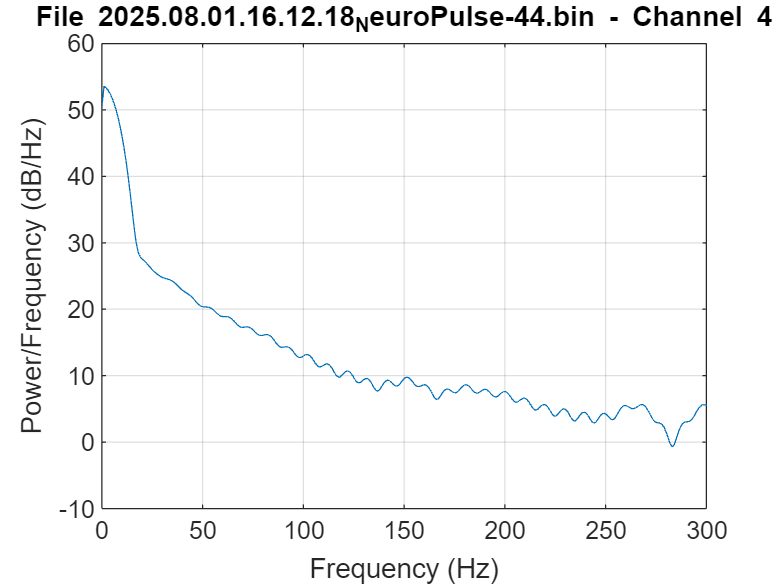

Processing file 2 of 5: 2025.08.01.16.43.55_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Progress: 100%
Unpacking Completed! 


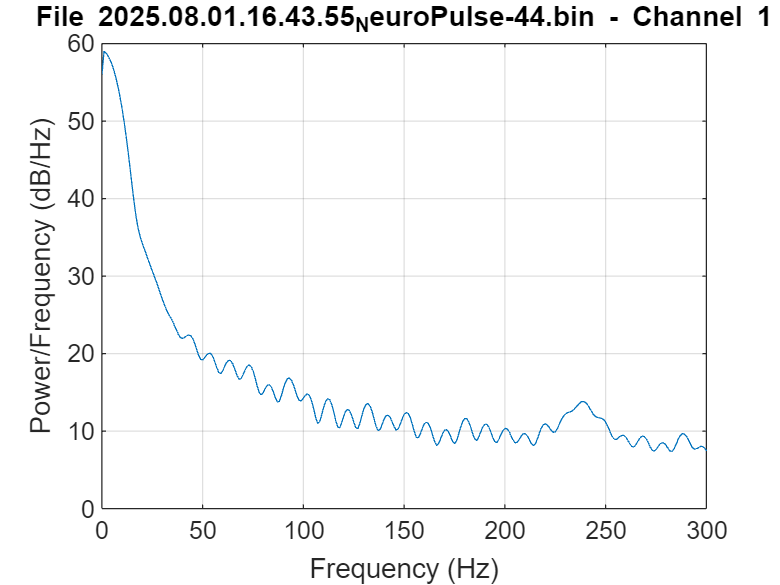

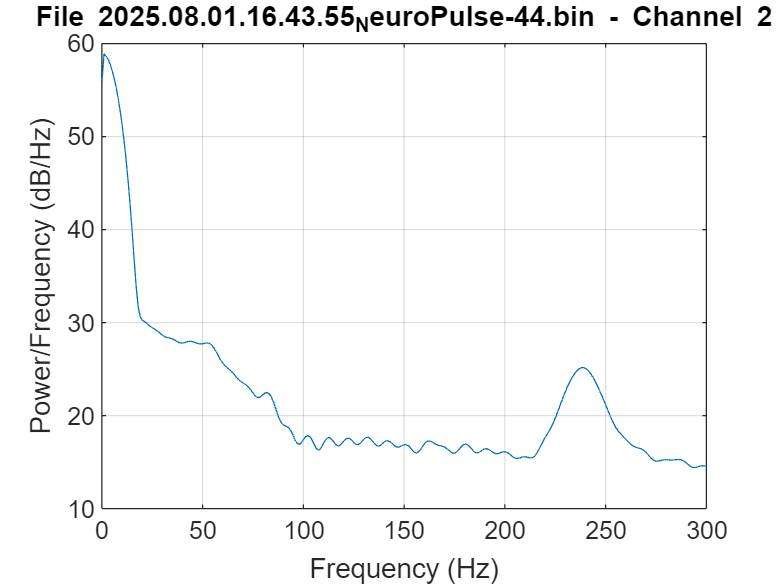

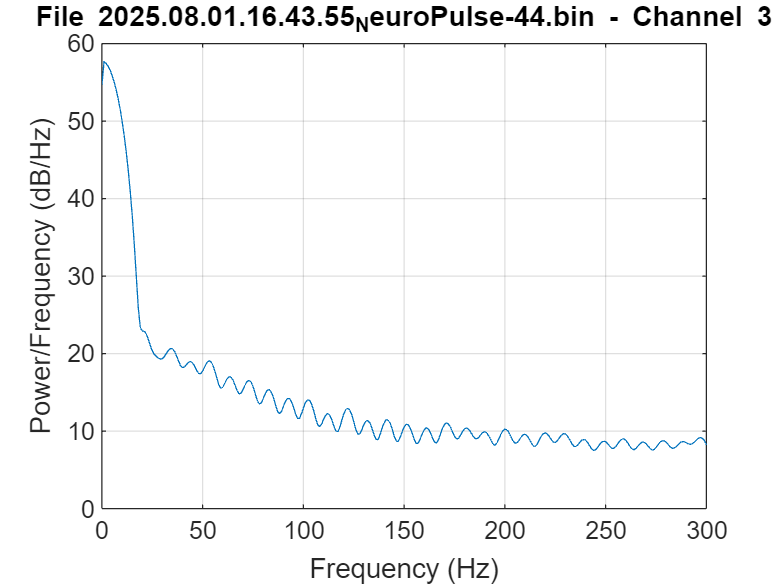

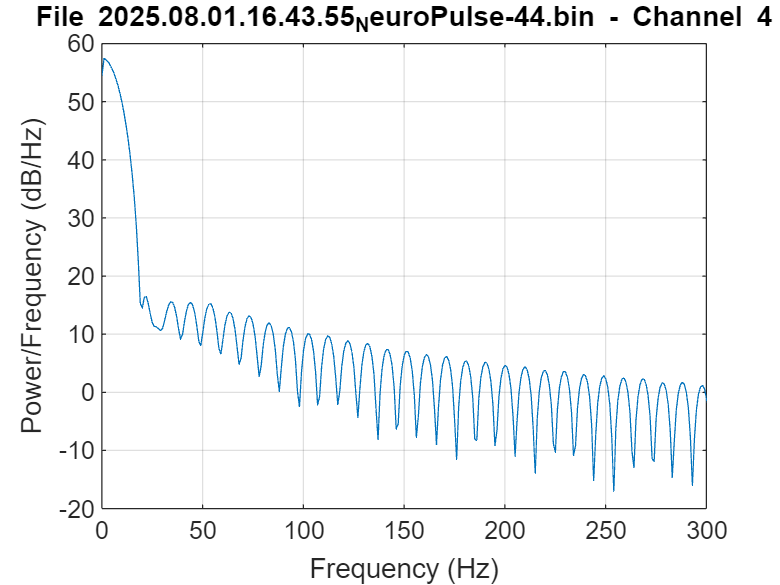

Processing file 3 of 5: 2025.08.01.16.45.11_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Progress: 100%
Unpacking Completed! 


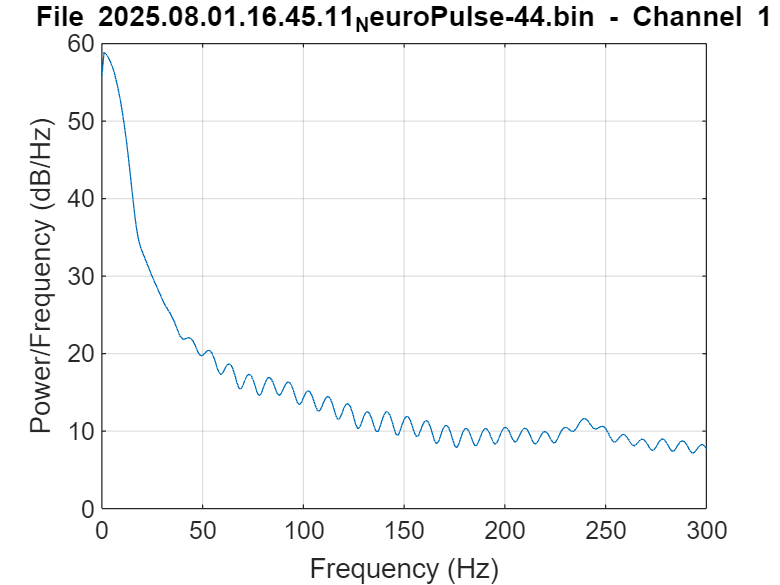

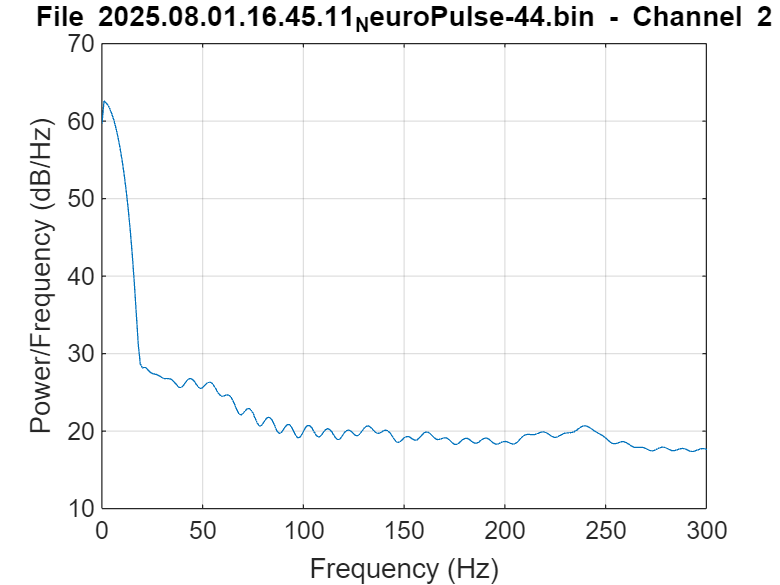

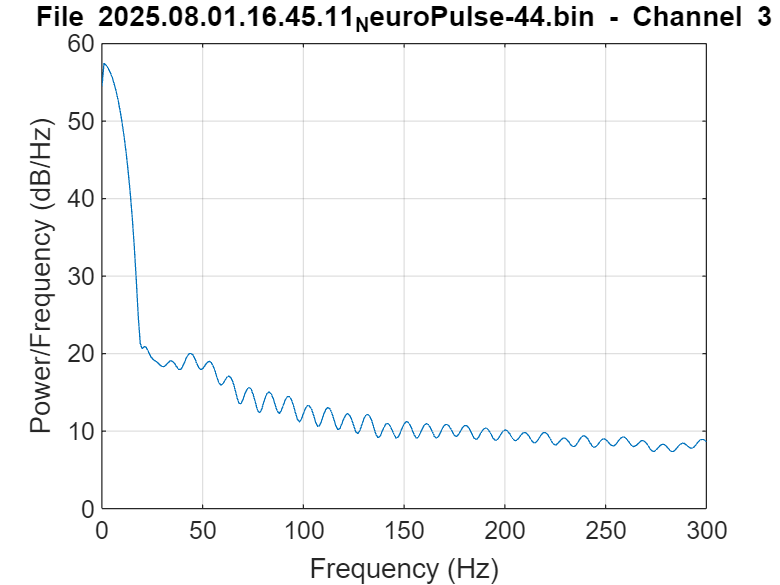

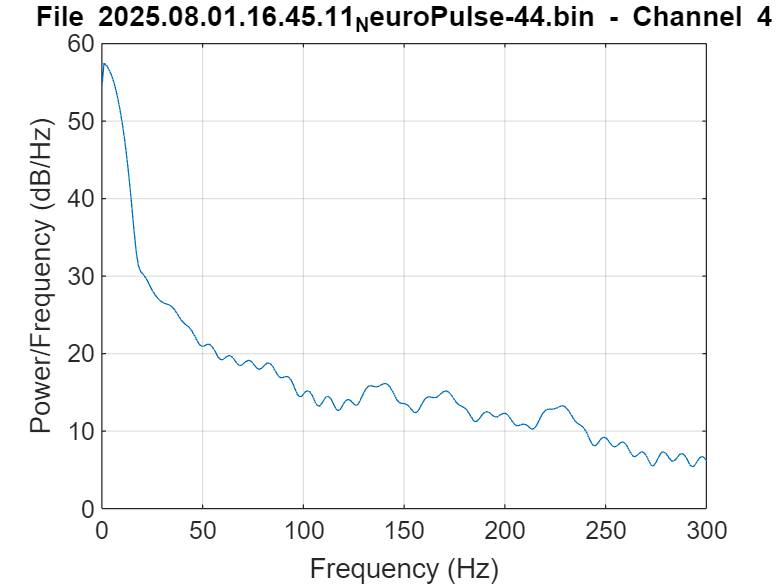

Processing file 4 of 5: 2025.08.01.16.51.07_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


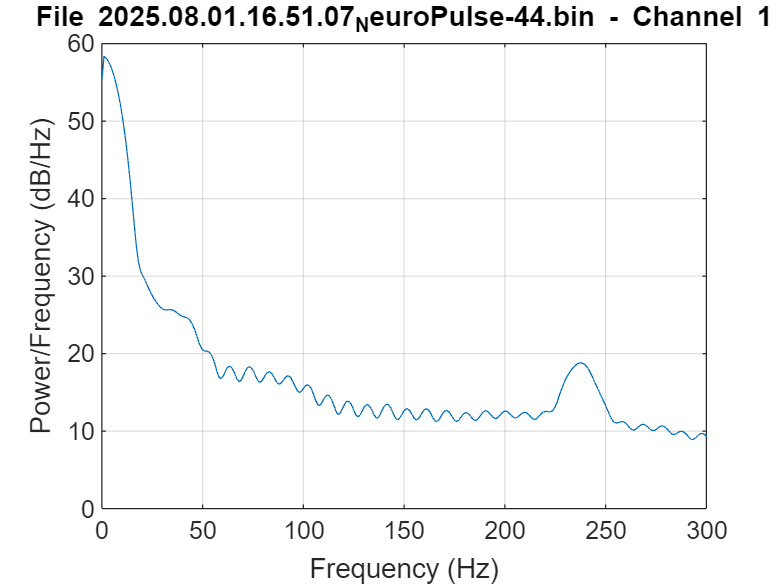

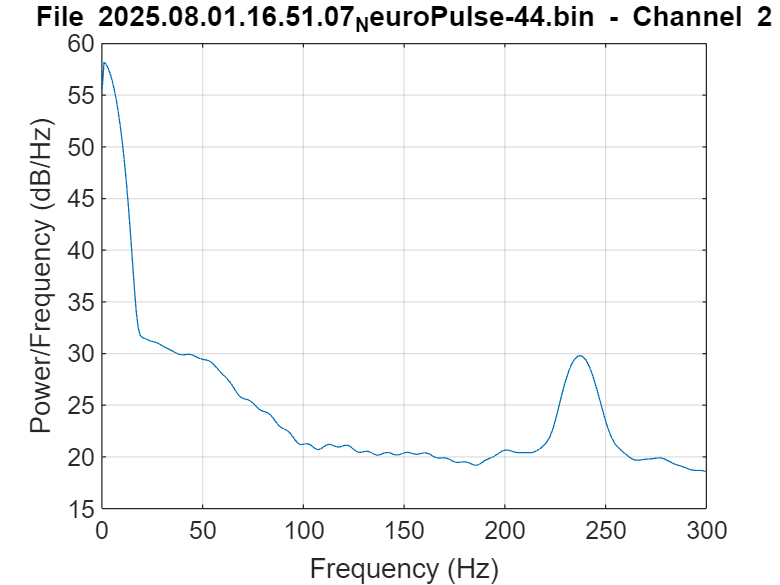

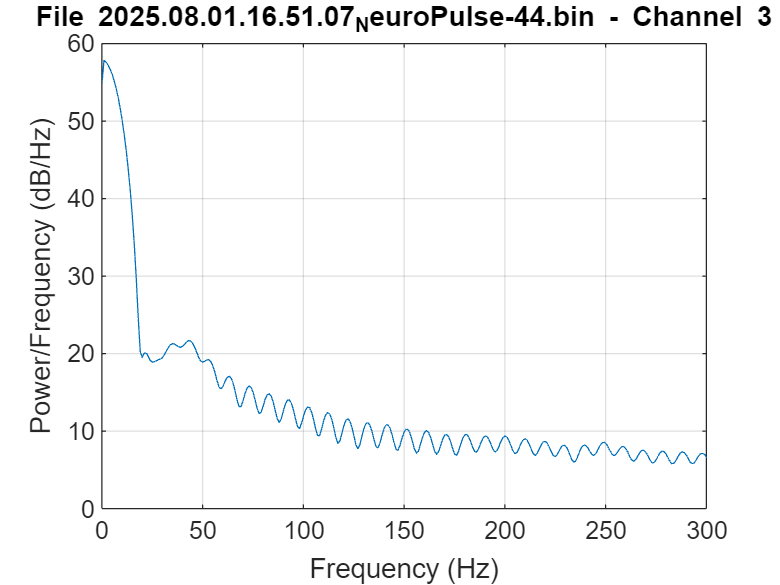

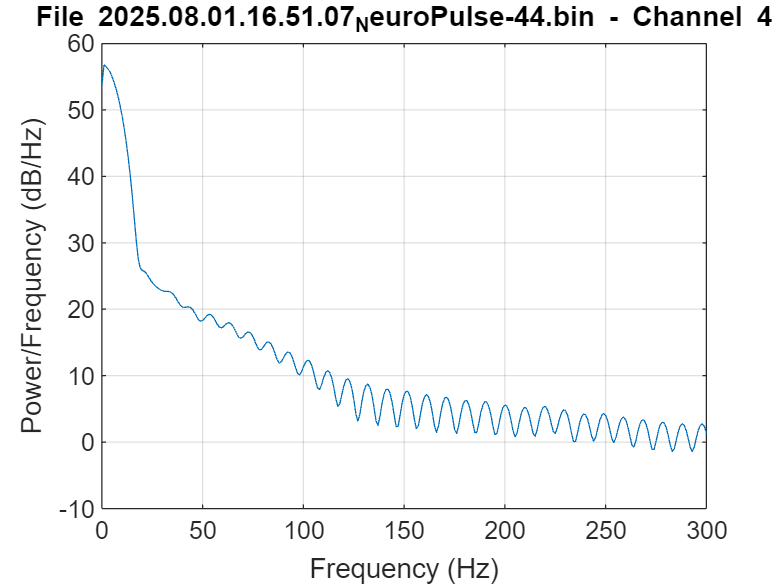

Processing file 5 of 5: 2025.08.01.16.59.13_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


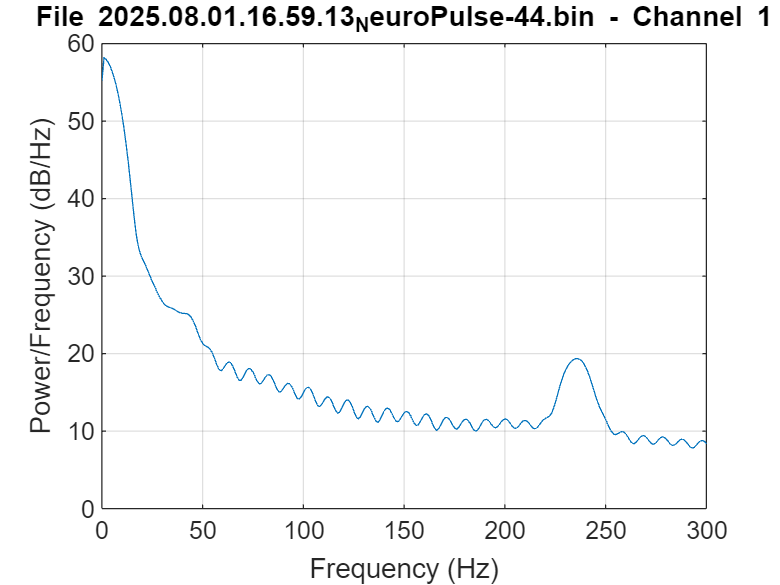

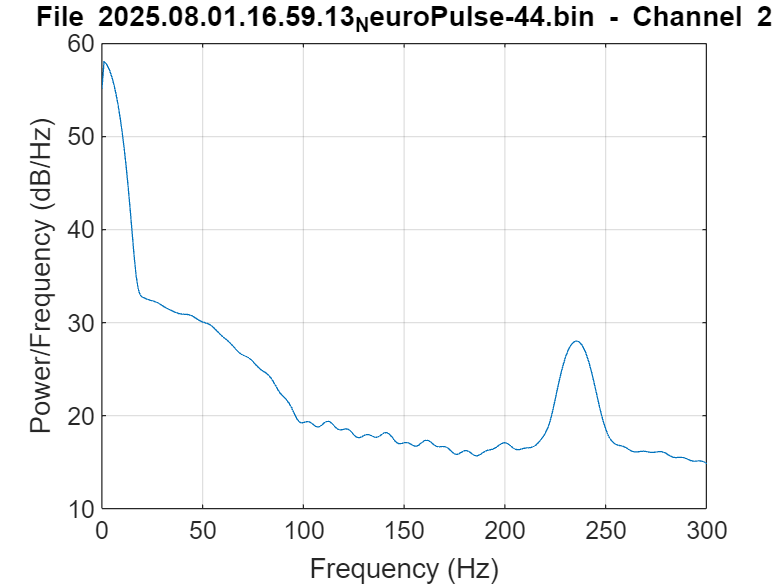

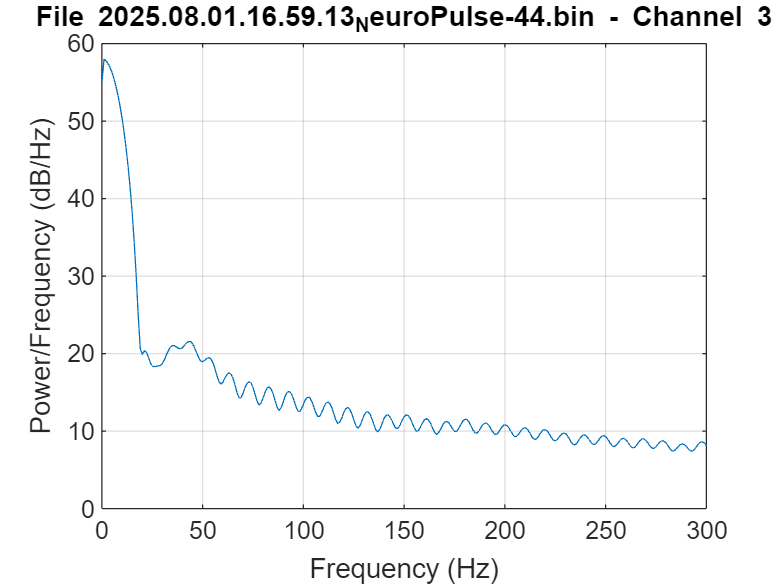

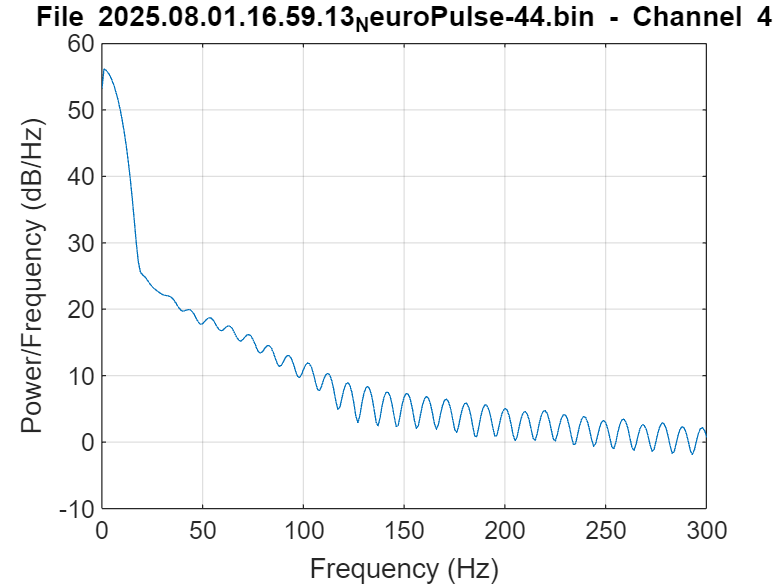

for i = 1:length(fileList)
    filePath = fullfile(folderPath, fileList(i).name);
        
        % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
        
        % Call your unpack function
     unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
        
        % Extract data
      data = unpackedFile.channelsData;
      t    = unpackedFile.time;
 
    for ch = 1:4
        figure;
        [Pxx,F] = pwelch(data(ch,:), hamming(1024), 512, 10000, 10000);
        plot(F,10*log10(Pxx))
        xlabel('Frequency (Hz)')
        ylabel('Power/Frequency (dB/Hz)')
        title(['File ', fileList(i).name, ' - Channel ', num2str(ch)])
        grid on
        xlim([0 300])

    end
end

% we can identify noisy and  good recosing from PSD and also slightly with statistical analysis .Also averge
% different  recoding can create new basline with low noise variance
 

%newData = zeros(size(data);

%t_=zeros(size(t);
%for i = 1:length(fileList)
    % Full file path
    %filePath = fullfile(folderPath, fileList(i).name);
    
    % Display progress
    %fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
    
    % Call your unpack function
    %unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    %data = unpackedFile.channelsData;
    %t    = unpackedFile.time;
   %if ~all(size(t )== size(t_)) && i > 0
      %fprintf("time not matched ")
      
    %end
    %t_=t;
    %newData=data+newData;
%end
%newData=newData/5;
%================================================================================================
%size(t)
%size(t_)
%class(t)
%class(t_)
%size(data)
%size(newData)
%class(data)
%class(newData)
%time of recording is different so it diffcult to perform avg

Processing file 1 of 5: 2025.08.01.16.12.18_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


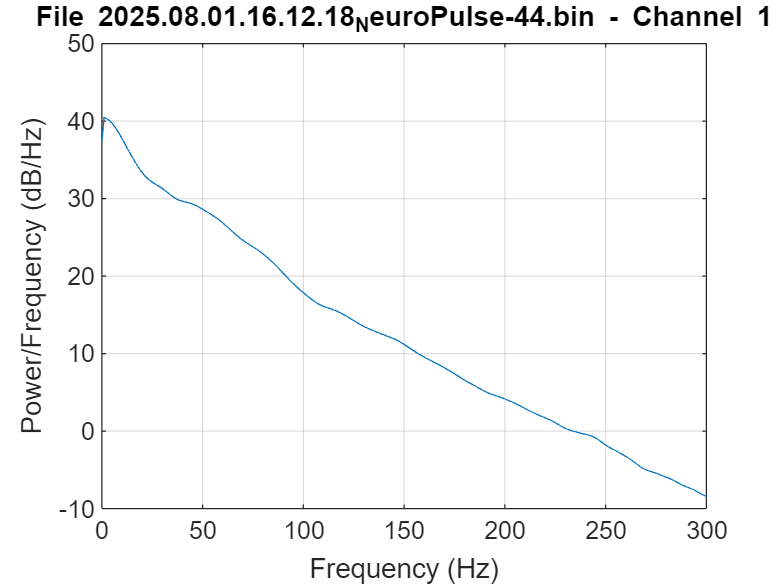

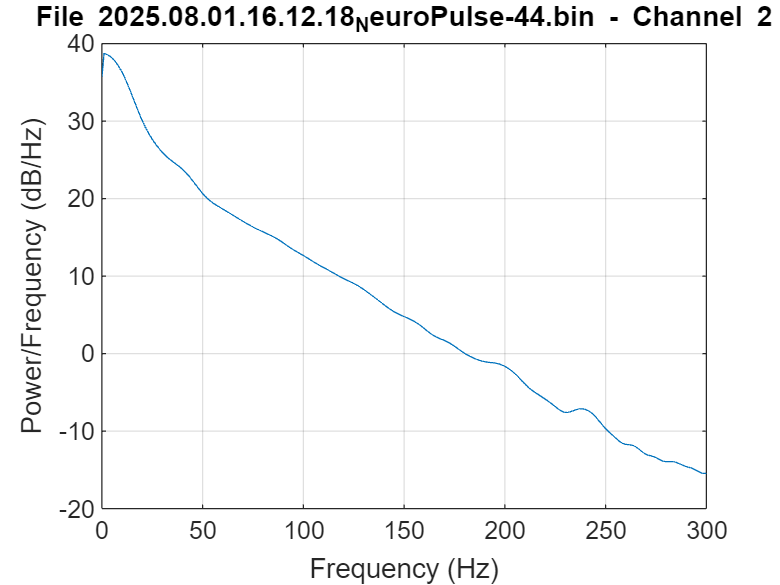

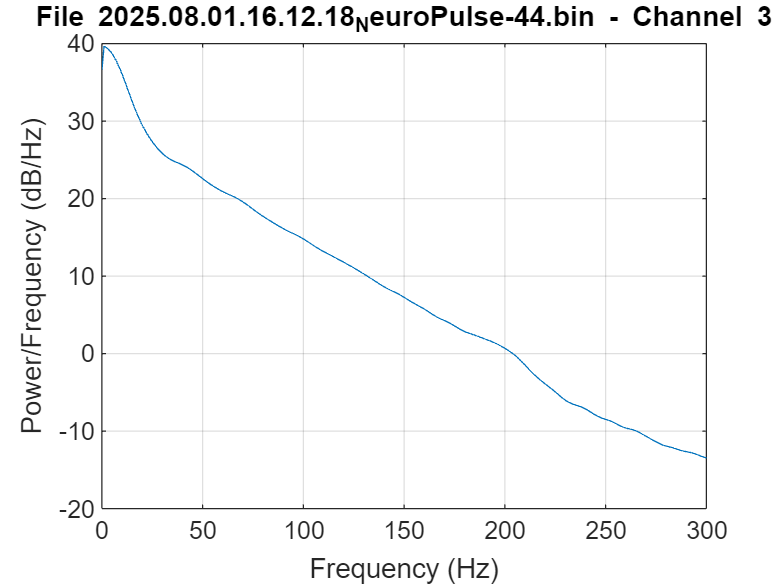

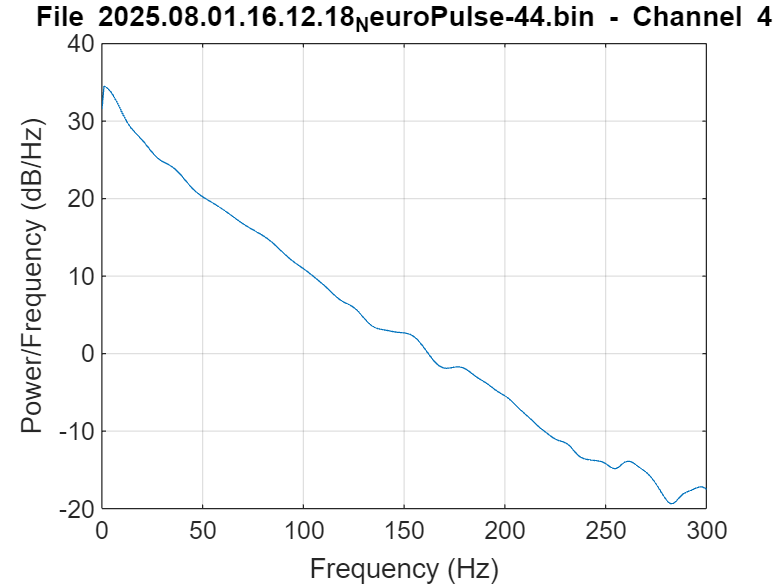

Processing file 2 of 5: 2025.08.01.16.43.55_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Progress: 100%
Unpacking Completed! 


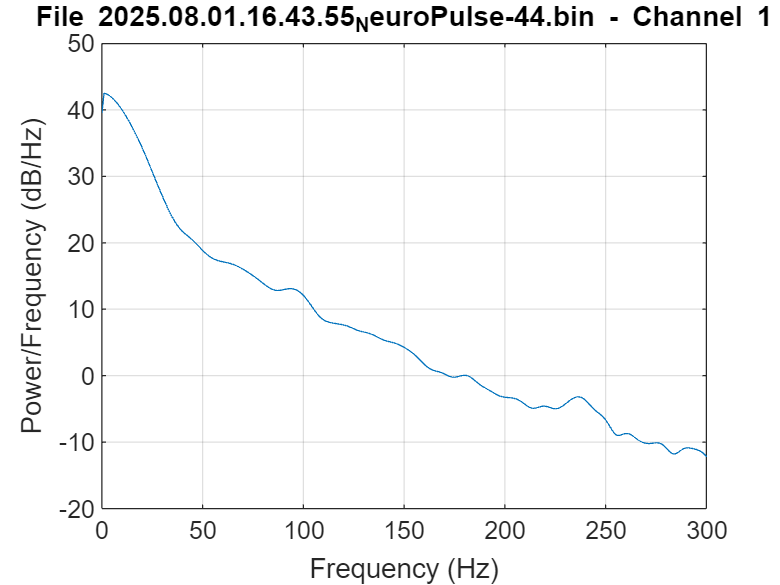

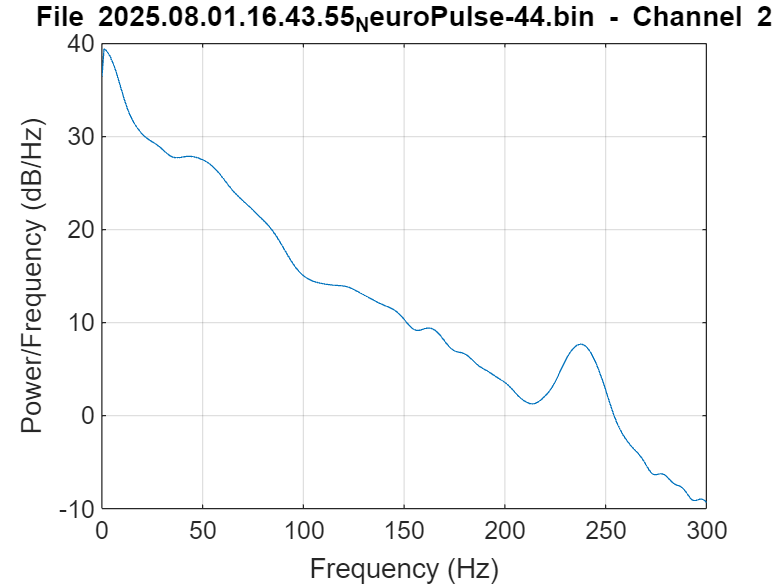

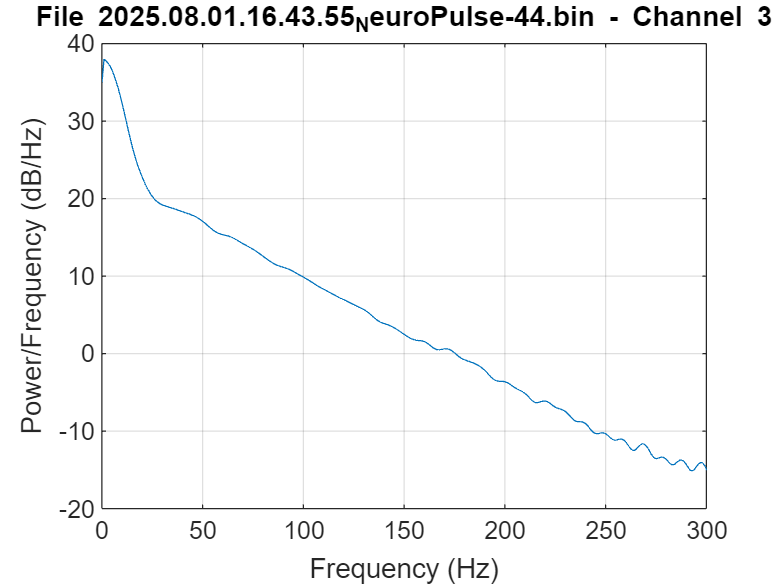

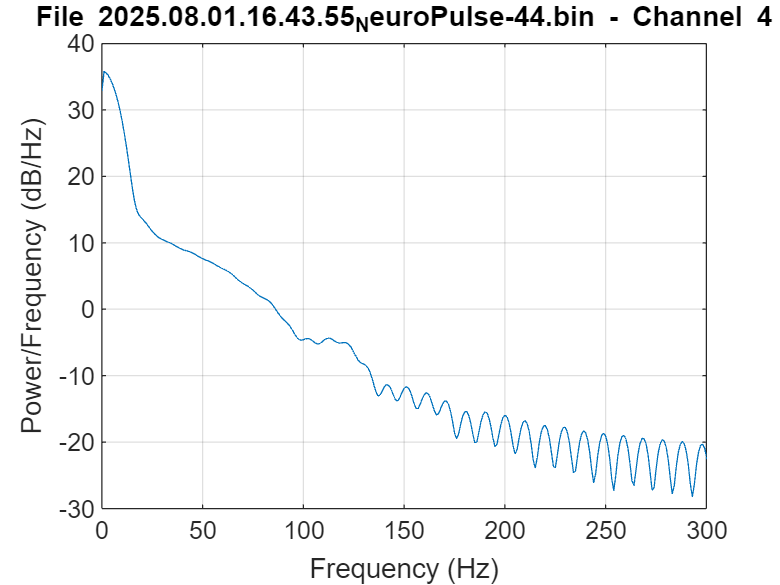

Processing file 3 of 5: 2025.08.01.16.45.11_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Progress: 100%
Unpacking Completed! 


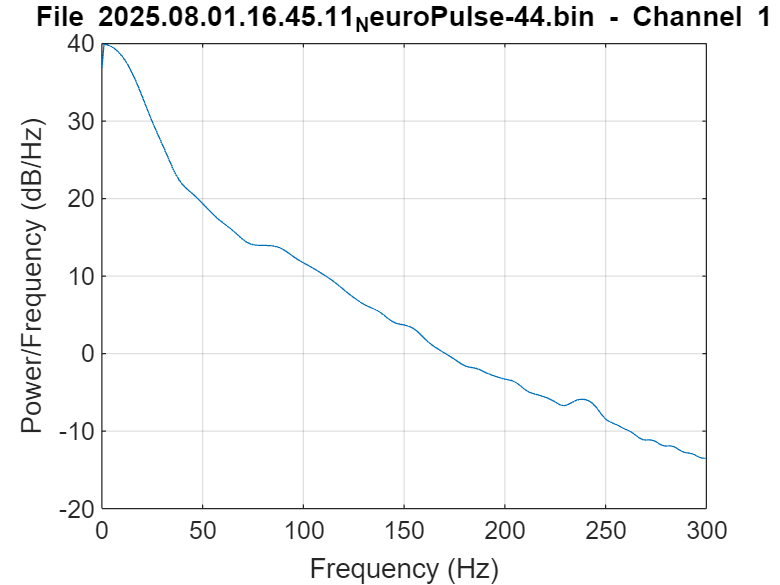

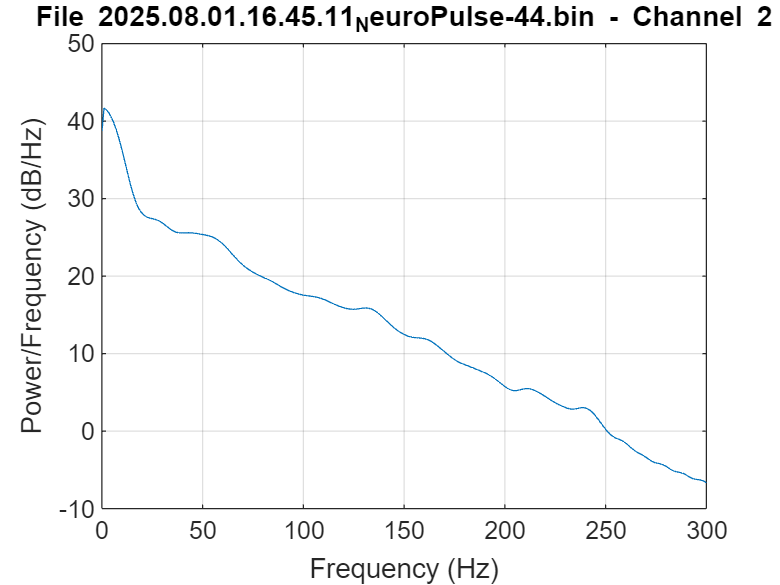

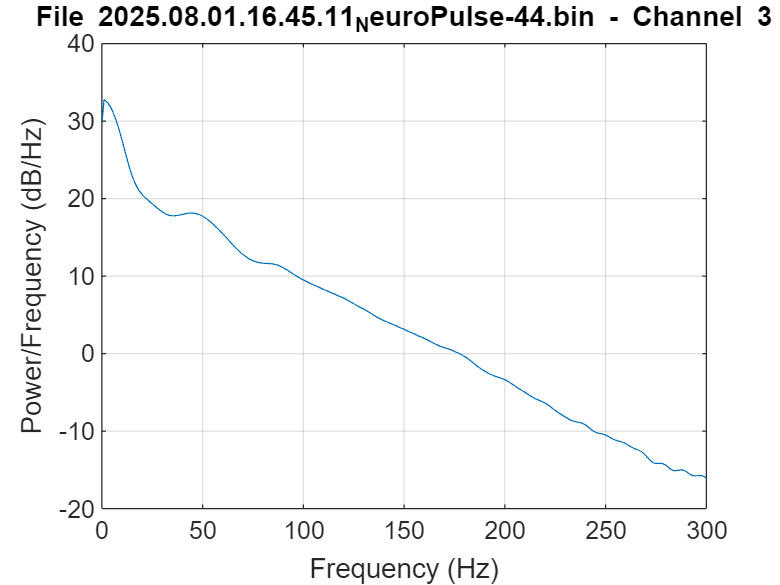

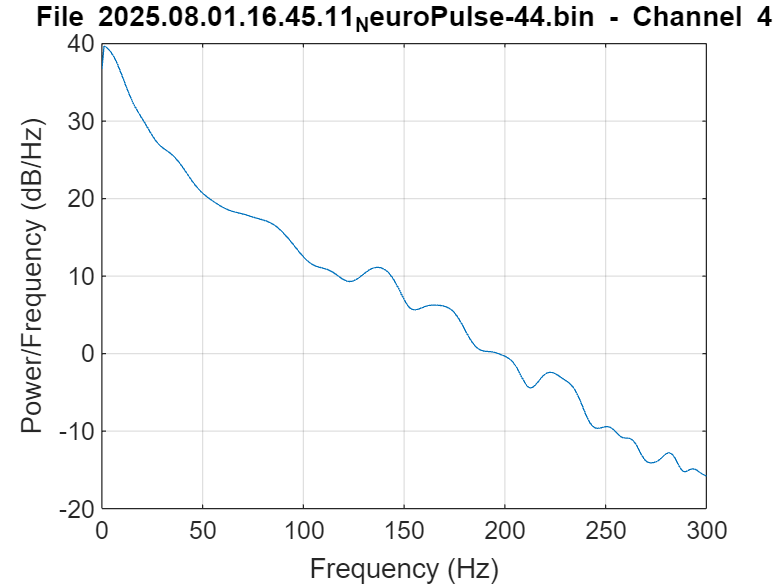

Processing file 4 of 5: 2025.08.01.16.51.07_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


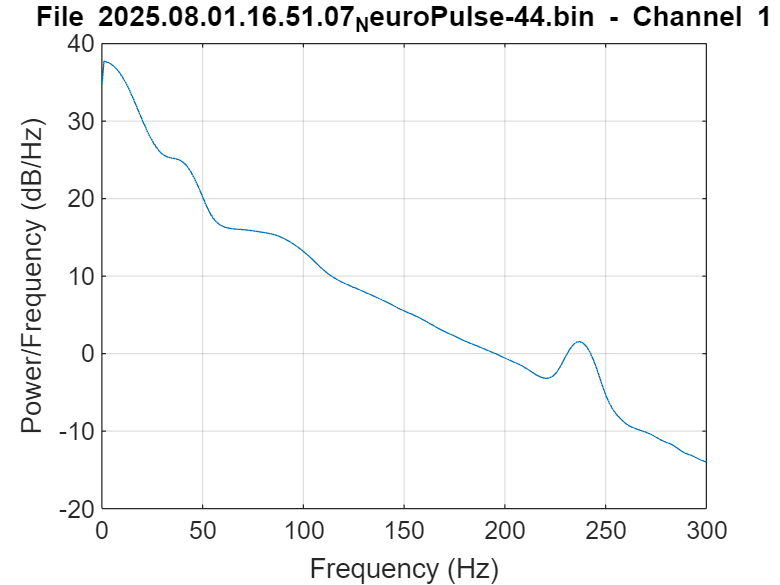

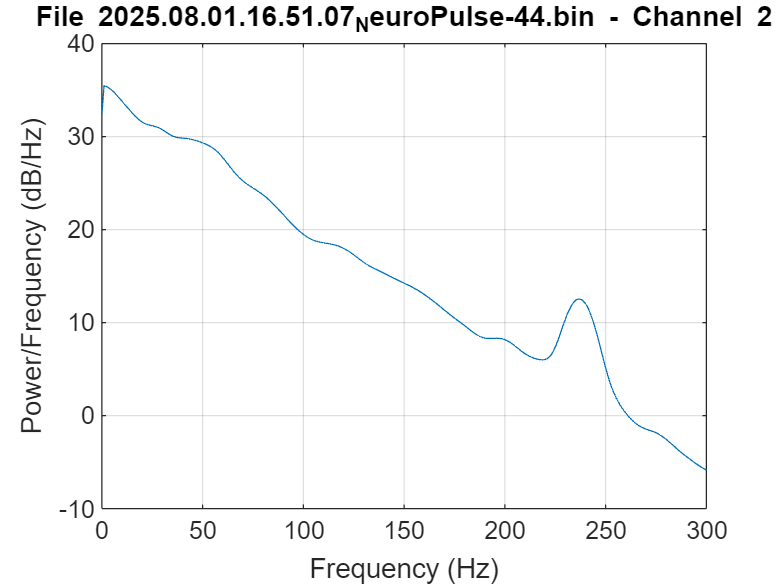

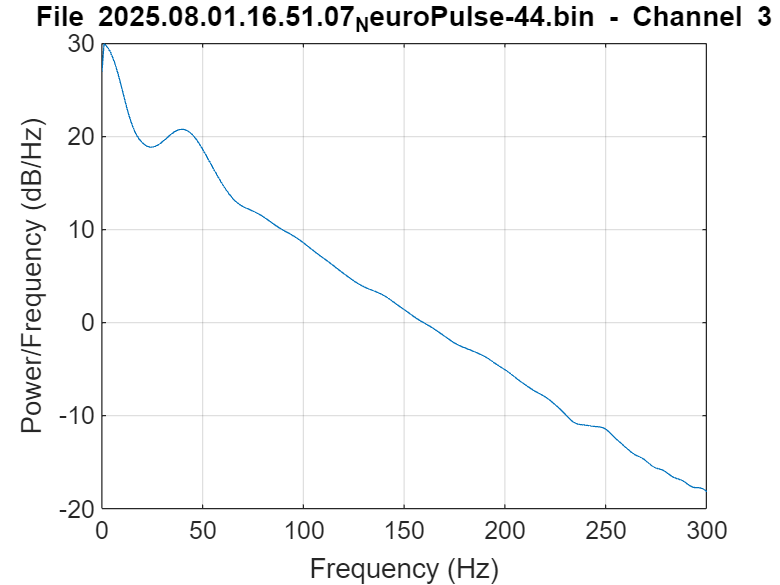

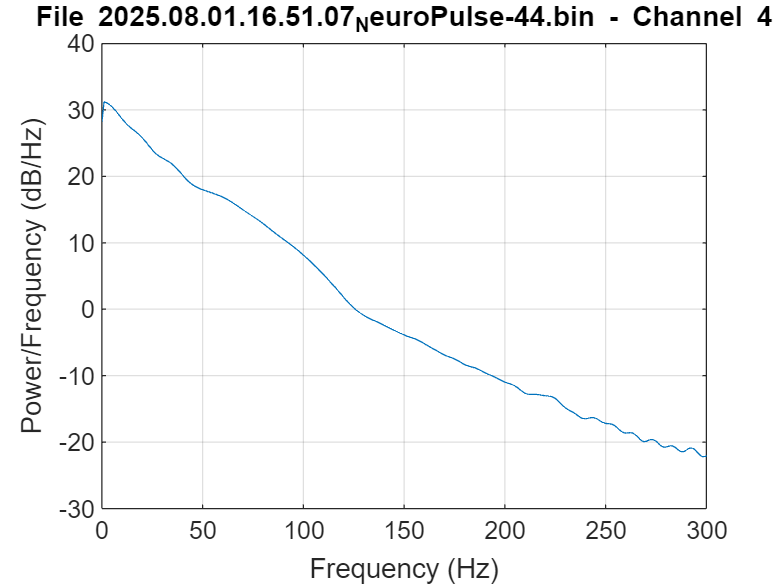

Processing file 5 of 5: 2025.08.01.16.59.13_NeuroPulse-44.bin


Unpacking Data from file... 
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Unpacking Completed! 


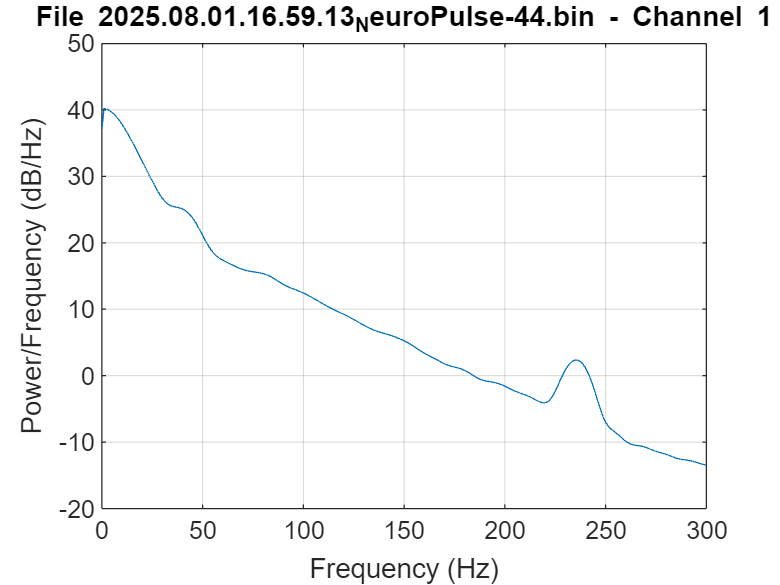

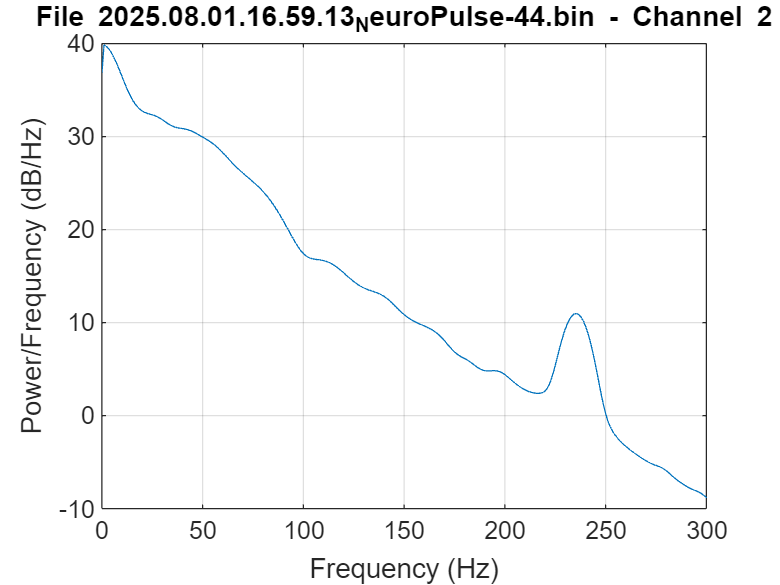

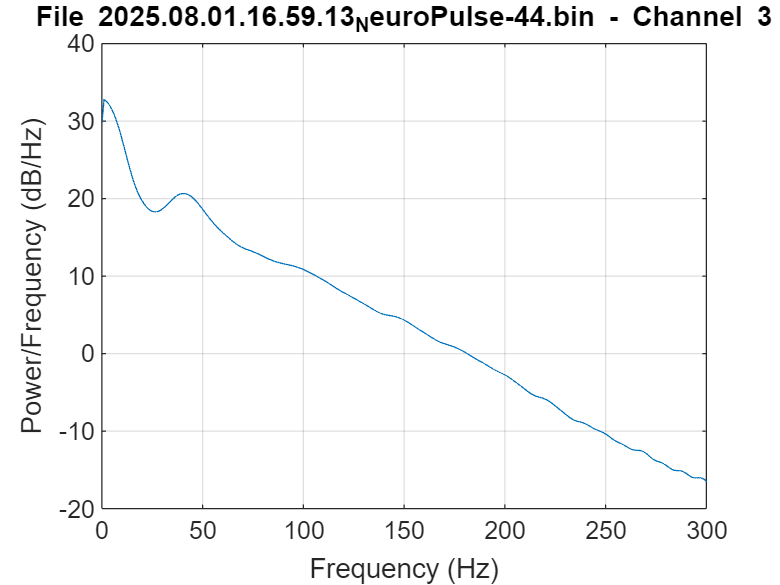

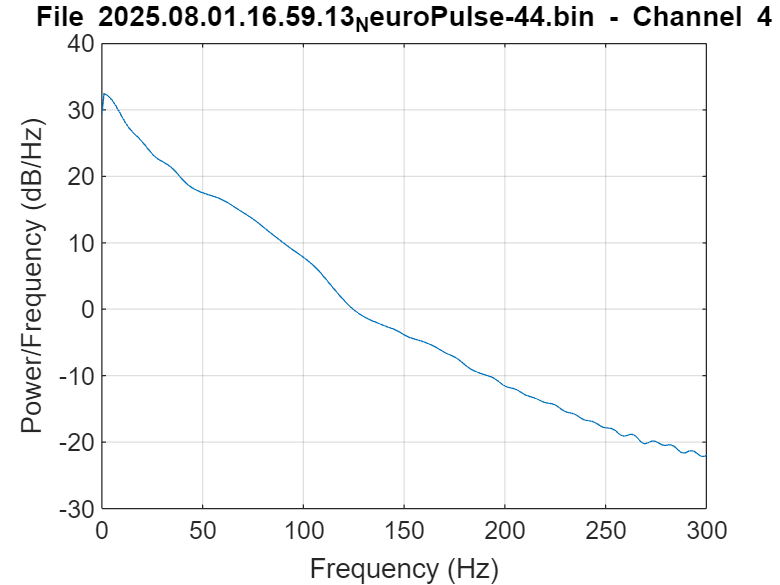

%filtering the basline and outlier removal or interchange
for i = 1:length(fileList)
    filePath = fullfile(folderPath, fileList(i).name);
    
    % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
    
    % Call your unpack function
    unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    data = unpackedFile.channelsData;
    t    = unpackedFile.time;
    cleaned = zeros(size(data));
    for ch = 1:4
        fs = 10000;  
        low_cutoff = 0.5;  
        high_cutoff = 150;
        
        % Nyquist = fs/2
        Wn = [low_cutoff high_cutoff] / (fs/2);
        
        % Design a 4th-order Butterworth bandpass filter
        [b,a] = butter(2, Wn, 'bandpass');%4th orders are tohigh not suitable will return NaN
        
        % Apply filter
        filtered_signal = filtfilt(b, a, data(ch,:));  %This cancels out the phase distortion and gives zero-phase filtering forward and backward filtering
        figure;
        [Pxx,F] = pwelch(filtered_signal, hamming(1024), 512, 10000, 10000);
        plot(F,10*log10(Pxx))
        xlabel('Frequency (Hz)')
        ylabel('Power/Frequency (dB/Hz)')
        title(['File ', fileList(i).name, ' - Channel ', num2str(ch)])
        grid on
        xlim([0 300])
        cleaned(ch,:) = filtered_signal;

    end
    eval(['cleaned_' num2str(i) ' = cleaned;']);
    filename = ['cleaned_' num2str(i) '.csv'];
    writematrix(cleaned, filename);
end

% Folder path (change to your "baseline" folder path)
folderPath_2 = "C:\Users\thamilezai\Downloads\JHU\Pre Work\My Work\Ephys recordings";
isfolder(folderPath_2)

ans = logical
   1




% Loop over each file
% Folder path (change to your "baseline" folder path)
folderPath = "C:\Users\thamilezai\Downloads\JHU\Pre Work\My Work\baseline";
isfolder(folderPath)

% Get a list of all files in the folder (.bin files)
fileList = dir(fullfile(folderPath, '*.bin'))
stdVals = zeros(5,4);
kurtVals = zeros(5,4);
skewVals = zeros(5,4);
names = zeros(5,4);

% Loop over each file
for i = 1:length(fileList)
    % Full file path
    filePath = fullfile(folderPath, fileList(i).name);
    
    % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
    
    % Call your unpack function
    unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    data = unpackedFile.channelsData;
    t    = unpackedFile.time;
    stdVals(i,1)  = std(data(1,:));
    stdVals(i,2)  = std(data(2,:));
    stdVals(i,3)  = std(data(3,:));
    stdVals(i,4)  = std(data(4,:));

     kurtVals(i,1)  = kurtosis(data(1,:));
     kurtVals(i,2)  = kurtosis(data(2,:));
     kurtVals(i,3)  = kurtosis(data(3,:));
     kurtVals(i,4)  = kurtosis(data(4,:));

     skewVals(i,1)  = skewness(data(1,:));
     skewVals(i,2)  = skewness(data(2,:));
     skewVals(i,3)  = skewness(data(3,:));
     skewVals(i,4)  = skewness(data(4,:));

    

    %Plot all channels
    figure;
    for ch = 1:unpackedFile.numChannels
        subplot(unpackedFile.numChannels,1,ch);
        plot(t, data(ch,:));
        xlabel('Time (s)');
        ylabel('Amplitude');
        title(['File: ', fileList(i).name, ' | Channel ', num2str(ch)]);
        grid on;
    end
end

stdTable   = table(names, stdVals,   'VariableNames', {'File','StdDev'});
kurtTable  = table(names, kurtVals,  'VariableNames', {'File','Kurtosis'});
skewTable  = table(names, skewVals,  'VariableNames', {'File','Skewness'});


stdTable = array2table(stdVals, ...
    'VariableNames', {'Channel1','Channel2','Channel3','Channel4'});
kurtTable = array2table(kurtVals, ...
    'VariableNames', {'Channel1','Channel2','Channel3','Channel4'});
skewTable = array2table(skewVals, ...
    'VariableNames', {'Channel1','Channel2','Channel3','Channel4'});

% Display results
disp('Standard Deviation Table:');
disp(stdTable);

disp('Kurtosis Table:');
disp(kurtTable);

disp('Skewness Table:');
disp(skewTable);

for i = 1:length(fileList)
    filePath = fullfile(folderPath, fileList(i).name);
        
        % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
        
        % Call your unpack function
     unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
        
        % Extract data
      data = unpackedFile.channelsData;
      t    = unpackedFile.time;
 
    for ch = 1:4
        figure;
        [Pxx,F] = pwelch(data(ch,:), hamming(1024), 512, 10000, 10000);
        plot(F,10*log10(Pxx))
        xlabel('Frequency (Hz)')
        ylabel('Power/Frequency (dB/Hz)')
        title(['File ', fileList(i).name, ' - Channel ', num2str(ch)])
        grid on
        xlim([0 300])

    end
end
% we can identify noisy and  good recosing from PSD and also slightly with statistical analysis .Also averge
% different  recoding can create new basline with low noise variance
 

%newData = zeros(size(data);

%t_=zeros(size(t);
%for i = 1:length(fileList)
    % Full file path
    %filePath = fullfile(folderPath, fileList(i).name);
    
    % Display progress
    %fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
    
    % Call your unpack function
    %unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    %data = unpackedFile.channelsData;
    %t    = unpackedFile.time;
   %if ~all(size(t )== size(t_)) && i > 0
      %fprintf("time not matched ")
      
    %end
    %t_=t;
    %newData=data+newData;
%end
%newData=newData/5;
%================================================================================================
%size(t)
%size(t_)
%class(t)
%class(t_)
%size(data)
%size(newData)
%class(data)
%class(newData)
%time of recording is different so it diffcult to perform avg

%filtering the basline and outlier removal or interchange
for i = 1:length(fileList)
    filePath = fullfile(folderPath, fileList(i).name);
    
    % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList), fileList(i).name);
    
    % Call your unpack function
    unpackedFile = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    data = unpackedFile.channelsData;
    t    = unpackedFile.time;
    cleaned = zeros(size(data));
    for ch = 1:4
        fs = 10000;  
        low_cutoff = 0.5;  
        high_cutoff = 150;
        
        % Nyquist = fs/2
        Wn = [low_cutoff high_cutoff] / (fs/2);
        
        % Design a 4th-order Butterworth bandpass filter
        [b,a] = butter(2, Wn, 'bandpass');%4th orders are tohigh not suitable will return NaN
        
        % Apply filter
        filtered_signal = filtfilt(b, a, data(ch,:));  %This cancels out the phase distortion and gives zero-phase filtering forward and backward filtering
        figure;
        [Pxx,F] = pwelch(filtered_signal, hamming(1024), 512, 10000, 10000);
        plot(F,10*log10(Pxx))
        xlabel('Frequency (Hz)')
        ylabel('Power/Frequency (dB/Hz)')
        title(['File ', fileList(i).name, ' - Channel ', num2str(ch)])
        grid on
        xlim([0 300])
        cleaned(ch,:) = filtered_signal;

    end
    eval(['cleaned_' num2str(i) ' = cleaned;']);
    filename = ['cleaned_' num2str(i) '.csv'];
    writematrix(cleaned, filename);
end

% Folder path (change to your "baseline" folder path)
folderPath_2 = "C:\Users\thamilezai\Downloads\JHU\Pre Work\My Work\Ephys recordings";
isfolder(folderPath_2)

% Get a list of all files in the folder (.bin files)
fileList_2 = dir(fullfile(folderPath_2, '*.bin'))


% Loop over each file
for i = 1:length(fileList_2)
    % Full file path
    filePath_2 = fullfile(folderPath_2, fileList_2(i).name);
    
    % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList_2), fileList_2(i).name);
    
    % Call your unpack function
    unpackedFile_2 = fn_BionodeBinOpen_2(filePath_2, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    data_2 = unpackedFile_2.channelsData;
    t_2    = unpackedFile_2.time;
   

  
    %Plot all channels
    figure;
    for ch = 1:unpackedFile_2.numChannels
        subplot(unpackedFile_2.numChannels,1,ch);
        plot(t_2, data_2(ch,:));
        xlabel('Time (s)');
        ylabel('Amplitude');
        title(['File: ', fileList_2(i).name, ' | Channel ', num2str(ch)]);
        grid on;
    end
end


for i = 1:length(fileList_2)
    filePath_2 = fullfile(folderPath_2, fileList_2(i).name);
    
    % Display progress
    fprintf('Processing file %d of %d: %s\n', i, length(fileList_2), fileList_2(i).name);
    
    % Call your unpack function
    unpackedFile_2 = fn_BionodeBinOpen_2(filePath, 12, 10000);  % (ADCres=12, sampR=10000 as example)
    
    % Extract data
    data_2 = unpackedFile_2.channelsData;
    t_2    = unpackedFile_2.time;
    cleaned_2 = zeros(size(data_2));
    snr_arr=zeros(5,4);
    for ch = 1:4
        fs = 10000;  
        low_cutoff = 0.5;  
        high_cutoff = 150;
        
        % Nyquist = fs/2
        Wn = [low_cutoff high_cutoff] / (fs/2);
        
        % Design a 4th-order Butterworth bandpass filter
        [b,a] = butter(2, Wn, 'bandpass');%4th orders are tohigh not suitable will return NaN
        
        % Apply filter
        filtered_signal_2 = filtfilt(b, a, data_2(ch,:));  %This cancels out the phase distortion and gives zero-phase filtering forward and backward filtering
        noise =data_2(ch,:)-filtered_signal_2;
        Snr_arr(i,ch)=snr(filtered_signal_2,noise);
        figure;
        [Pxx,F] = pwelch(filtered_signal_2, hamming(1024), 512, 10000, 10000);
        plot(F,10*log10(Pxx))
        xlabel('Frequency (Hz)')
        ylabel('Power/Frequency (dB/Hz)')
        title(['File ', fileList_2(i).name, ' - Channel ', num2str(ch)])
        grid on
        xlim([0 300])
        cleaned_2(ch,:) = filtered_signal_2;

    end
    eval(['cleaned_Ephy_' num2str(i) ' = cleaned_2;']);
    filename_2 = ['cleaned_Ephy_' num2str(i) '.csv'];
    writematrix(cleaned_2, filename_2);
end

snrTable = array2table(snr_arr, ...
    'VariableNames', {'Channel1','Channel2','Channel3','Channel4'});